clear
clc

Extract Files

folder = fullfile("C:\Users\jamie\Documents\MATLAB\June2023Paper" + ...
    "\SignalDataset\GD\frm");
tds=tabularTextDatastore(folder,"IncludeSubfolders" ...
    ,true,"FileExtensions",".txt");

Creating Array of Tables.

ii = 1;
sds=[];
for ii = 1:numel(tds.Files)
    ts=importdata(tds.Files{ii});
    Ts=ts.data;
    sds=[sds Ts(:,2)];
end

Creating Time Domain

t=importdata(tds.Files{1});
time=t.data;
time=time(:,1);

Remove DC offset.

oo=1;
SDS=[];
for oo = 1:width(sds)
   SDS = [SDS sds(:,oo)-mean(sds(:,oo))];
end

Align the signals to the risetime

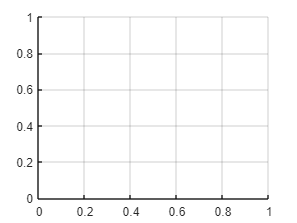

%SD=SDS(:,1);
SD=[];
for pp = 1 : width(SDS)
    [y1,y2]=alignsignals(SDS(:,3),SDS(:,pp),Method="maxpeak");
    delta=length(y2)-501;
    hold on
    y2(end-delta:end)=[];
    SD=[SD y2];
    hold on
end
grid on 

Multiply signal data by factor so that it equals 30 pasclas

SD=(SD/10)/0.012;

Take the average of aligned data.

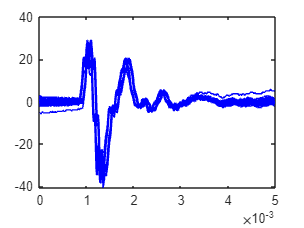

figure
plot(time,SD,"-b")
MSD=mean(SD,2);
hold on

Create Logarithmic series.

% Parameters
startValue = 2000; % Starting value of the series
base = 1.15; % Base of the logarithm
numElements = 18; % Number of elements in the series

% Create the logarithmic series
series = startValue * power(base, 0:numElements-1);

% Display the series
disp(series)

   1.0e+04 *

  Columns 1 through 7

    0.2000    0.2300    0.2645    0.3042    0.3498    0.4023    0.4626

  Columns 8 through 14

    0.5320    0.6118    0.7036    0.8091    0.9305    1.0701    1.2306

  Columns 15 through 18

    1.4151    1.6274    1.8715    2.1523



Perform frequency analysis on scattered signal

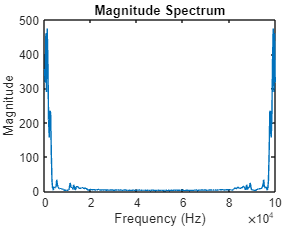

Signal=MSD(160:end);
% Signal parameters
signalLength = length(Signal); % Length of the signal
samplingFrequency = 100e3; % Sampling frequency in Hz
% Perform the FFT
fftSignal = fft(Signal);
% Compute the frequency axis
frequencyAxis = linspace(0, samplingFrequency, signalLength);

% Find the index corresponding to the desired frequency component
desiredFrequency = series; % Frequency component of interest in Hz
F=[];
for jj=1:length(series)
[~, index] = min(abs(frequencyAxis - desiredFrequency(jj)));
% Extract the magnitude of the desired frequency component
magnitude = abs(fftSignal(index));
F=[F magnitude];
end

FS =     0.1715  156.1050
    0.1491  234.3448
    0.1297  229.9561
    0.1128  112.4443
    0.0981    6.6079
    0.0853   12.3010
    0.0741    9.5709
    0.0645   32.8984
    0.0561    8.3095
    0.0488    6.6649
